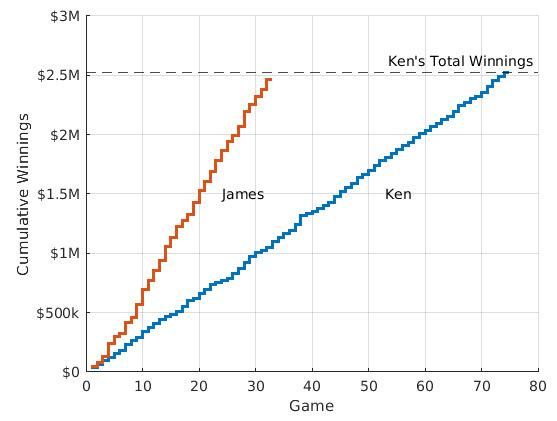

Load Data

James = urlread('https://thejeopardyfan.com/statistics/james-holzhauer-jeopardy-statistics');
Ken = urlread('https://thejeopardyfan.com/statistics/ken-jennings-final-statistics');

# Extract Dates

James

pattern1 = '<td class="column-2">';
pattern2 = '</td>';
datesJames = extractBetween(James, pattern1,pattern2);
datesJames = datesJames(1:end-1);
gamesJames = (1:length(datesJames))';
% datesJames = cell2table(datesJames);
% datesJames = datetime(datesJames.datesJames,'InputFormat','yyyy-MM-dd');

Ken

datesKen = extractBetween(Ken,pattern1,pattern2);
datesKen = datesKen(1:75);
gamesKen = (1:75)';

#### Daily Winnings

James

pattern1 = '<td class="column-3">';
pattern2 = '</td>';
JamesWinnings = extractBetween(James,pattern1,pattern2);
JamesWinnings = JamesWinnings(1:end-1);
JamesWinnings = strrep(JamesWinnings, '$', '');
JamesWinnings = strrep(JamesWinnings, ',', '');
JamesWinnings = str2double(JamesWinnings);

Ken

KenWinnings = extractBetween(Ken,pattern1,pattern2);
KenWinnings = KenWinnings(1:75);
KenWinnings = strrep(KenWinnings, '$', '');
KenWinnings = strrep(KenWinnings, ',', '');
KenWinnings = str2double(KenWinnings);

#### Number Correct

James

pattern1 = '<td class="column-4">';
pattern2 = '</td>';
JamesCorrect = extractBetween(James,pattern1,pattern2);
JamesCorrect = JamesCorrect(1:end-1);
JamesCorrect = str2double(JamesCorrect);

Ken

KenCorrect = extractBetween(Ken,pattern1,pattern2);
KenCorrect = KenCorrect(1:75);
KenCorrect = str2double(KenCorrect);

Plots

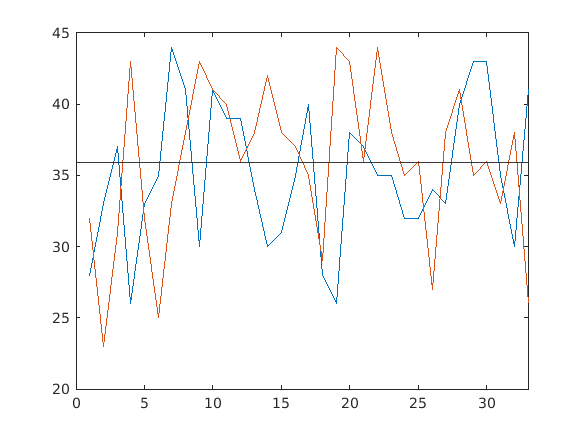

plot(gamesKen,KenCorrect)
yline(mean(KenCorrect));
hold on
plot(gamesJames,JamesCorrect)
yline(mean(JamesCorrect));
hold off
xlim([0 max(gamesJames)])

#### Number Incorrect

James

pattern1 = '<td class="column-5">';
pattern2 = '</td>';
JamesIncorrect = extractBetween(James,pattern1,pattern2);
JamesIncorrect = JamesIncorrect(1:end-1);
JamesIncorrect = str2double(JamesIncorrect);

Ken

KenIncorrect = extractBetween(Ken,pattern1,pattern2);
KenIncorrect = KenIncorrect(1:75);
KenIncorrect = str2double(KenIncorrect);

Plots

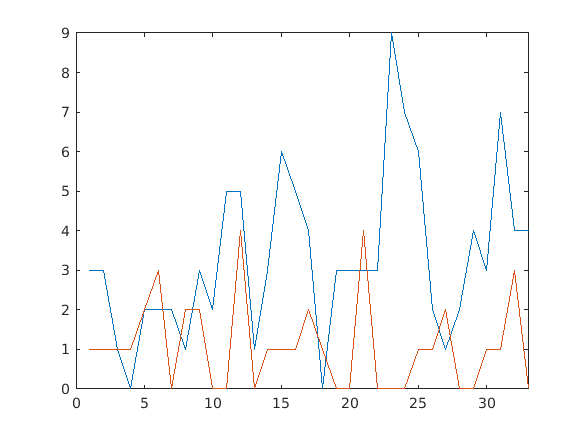

plot(gamesKen,KenIncorrect)
hold on
plot(gamesJames,JamesIncorrect)
hold off
xlim([0 max(gamesJames)])

#### Cumulative Winnings

Ken

KenCumWin = cumsum(KenWinnings);

James

JamesCumWin = cumsum(JamesWinnings);

Plots

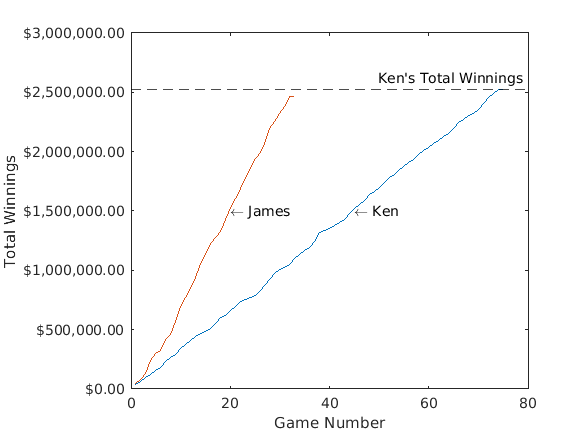

plot(gamesKen,KenCumWin)
text(45,1500000,'\leftarrow Ken')
hold on
plot(gamesJames,JamesCumWin)
text(20,1500000,'\leftarrow James')
hold off
xlabel('Game Number')
ylabel('Total Winnings')
ytickformat('usd')
yline(max(KenCumWin),'k--',"Ken's Total Winnings");

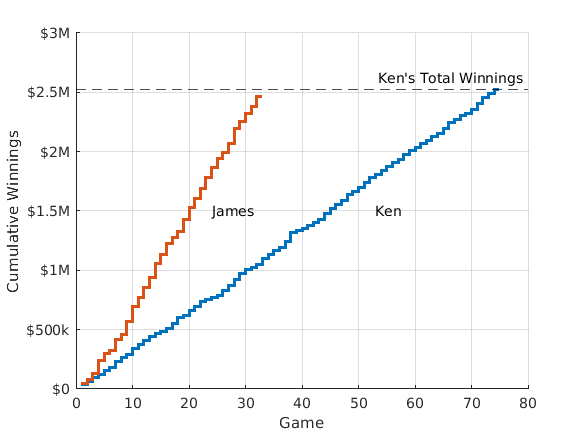


stairs(gamesKen,KenCumWin,'LineWidth',2)
text(53,1500000,'Ken')
hold on
stairs(gamesJames,JamesCumWin,'LineWidth',2)
text(24,1500000,'James')
hold on
% x= max(gamesJames):1:max(gamesKen); 
% y= mean(JamesWinnings)*x;
% plot(x,y,'r--')
% hold on
% plot(75,max(y),'kx')
hold off
xlabel('Game')
ylabel('Cumulative Winnings')
ytickformat('usd')
yline(max(KenCumWin),'k--',"Ken's Total Winnings");
yticks([0 500000 1000000 1500000 2000000 2500000 3000000])
yticklabels({'$0','$500k','$1M','$1.5M','$2M','$2.5M','$3M'})
%xline(33,'k--','Record Broken Prediction (33)')
% text(55,max(y)-20000,num2str((max(y))))
box off;
ax = gca;
ax.YGrid = "on";
ax.XGrid = 'on';

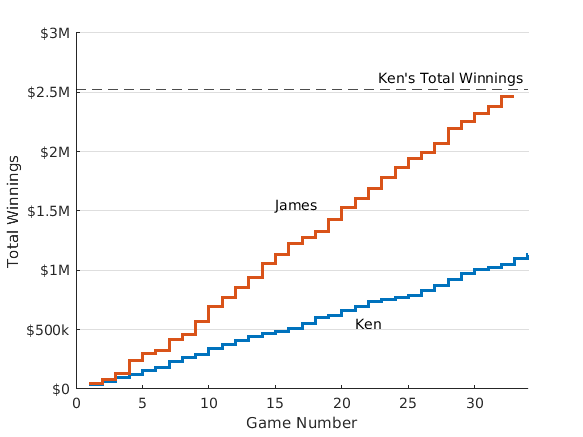


stairs(gamesKen,KenCumWin,'LineWidth',2)
text(21,550000,'Ken')
hold on
stairs(gamesJames,JamesCumWin,'LineWidth',2)
text(15,1550000,'James')
hold on
%plot(75,max(y),'ko')
hold off
xlabel('Game Number')
ylabel('Total Winnings')
yticks([0 500000 1000000 1500000 2000000 2500000 3000000])
yticklabels({'$0','$500k','$1M','$1.5M','$2M','$2.5M','$3M'})
yline(max(KenCumWin),'k--',"Ken's Total Winnings");
%text(55,max(y)-20000,num2str((max(y))))
xlim([0 length(gamesJames)+1])
ax = gca;
ax.YGrid = 'on';
box off;

#### Cumulative Correct and Incorrect Answers

Ken

KenCumCorrect = cumsum(KenCorrect);
KenCumIncorrect = cumsum(KenIncorrect);

James

JamesCumCorrect = cumsum(JamesCorrect);
JamesCumIncorrect = cumsum(JamesIncorrect);

Plots

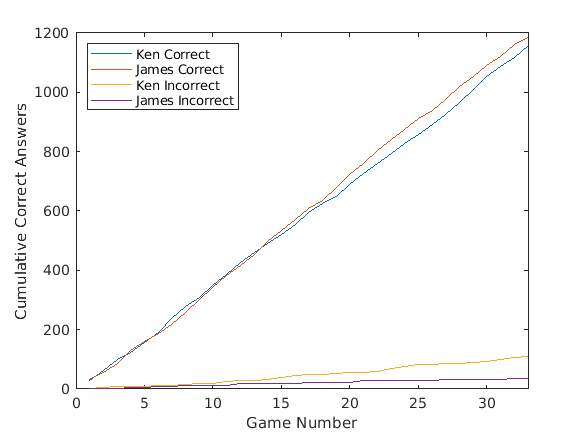

plot(gamesKen,KenCumCorrect)
%text(45,1500000,'\leftarrow Ken')
hold on
plot(gamesJames,JamesCumCorrect)
%text(20,1500000,'\leftarrow James')
hold on
plot(gamesKen,KenCumIncorrect)
hold on
plot(gamesJames,JamesCumIncorrect)
hold off
xlabel('Game Number')
ylabel('Cumulative Correct Answers')
legend('Ken Correct','James Correct','Ken Incorrect','James Incorrect','location','northwest')
xlim([0 max(gamesJames)])

#### Coryat Scores

Ken

pattern1 = '<td class="column-6">';
pattern2 = '</td>';
KenCoryat = extractBetween(Ken,pattern1,pattern2);
KenCoryat = KenCoryat(1:75);
KenCoryat = strrep(KenCoryat, '$', '');
KenCoryat = strrep(KenCoryat, ',', '');
KenCoryat = str2double(KenCoryat);

James

JamesCoryat = extractBetween(James,pattern1,pattern2);
JamesCoryat = JamesCoryat(1:end-1);
JamesCoryat = strrep(JamesCoryat, '$', '');
JamesCoryat = strrep(JamesCoryat, ',', '');
JamesCoryat = str2double(JamesCoryat);

Plots

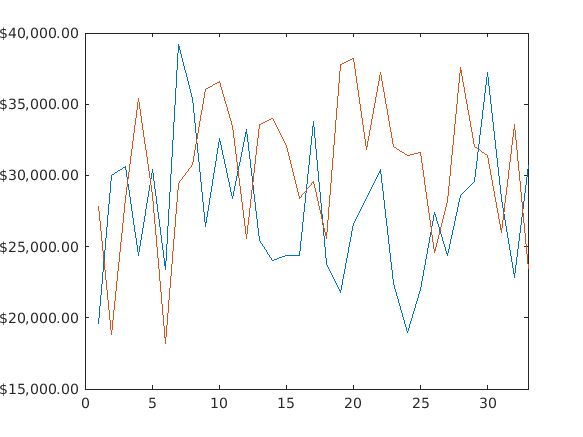

plot(gamesKen,KenCoryat)
hold on
plot(gamesJames,JamesCoryat)
hold off
xlim([0 max(gamesJames)])
ytickformat('usd')

#### Dominance 

Ken

pattern1 = '<td class="column-11">';
pattern2 = '</td>';
KenDom = extractBetween(Ken,pattern1,pattern2);
KenDom = KenDom(1:75);
KenDom = str2double(KenDom);

James

JamesDom = extractBetween(James,pattern1,pattern2);
JamesDom = JamesDom(1:end-1);
JamesDom = str2double(JamesDom);

Plots

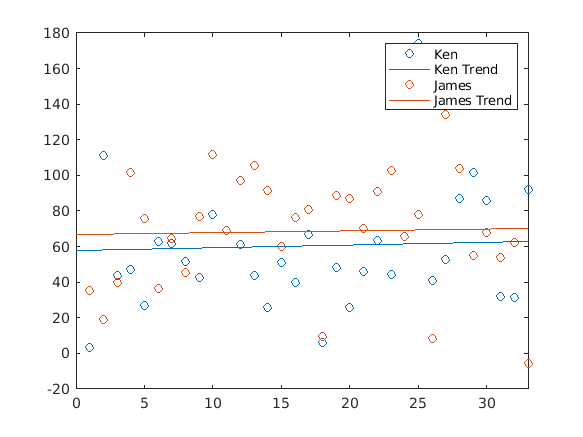

plot(gamesKen,KenDom,'o')
lsline
hold on
plot(gamesJames,JamesDom,'o')
lsline
hold off
xlim([0 length(gamesJames)])
legend('Ken','Ken Trend','James','James Trend')

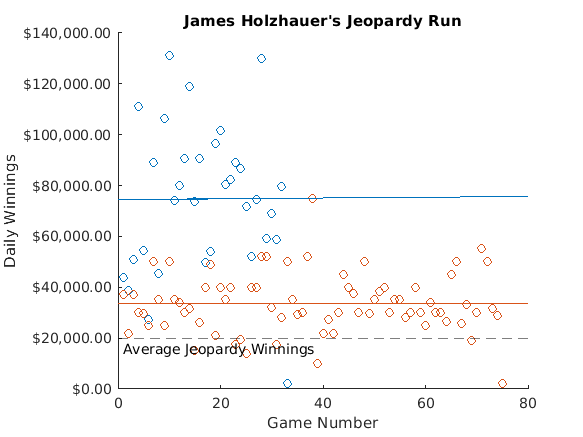

plot(gamesJames,JamesWinnings,'o','Color','#0072BD')
hold on
lsline
plot(gamesKen,KenWinnings,'o','Color','#D95319')
lsline
hold off
title("James Holzhauer's Jeopardy Run")
xlabel('Game Number')
ylabel('Daily Winnings')
ytickformat('usd')
ylim([0 140000])
%xlim([0 length(gamesJames)+1])
%yline(77000,'r:','Previous Single Day Record','LabelVerticalAlignment','bottom','LabelHorizontalAlignment','left');
yline(19980.15,'k--',"Average Jeopardy Winnings",'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','left','Alpha',.5);
%yline(mean(JamesWinnings),'--',"James' Average Winnings",'LabelHorizontalAlignment','left','Color','#0072BD');
%yline(mean(KenWinnings),'--',"Ken's Average Winnings",'LabelHorizontalAlignment','left','Color','#D95319');
box off;